# **Ubicación de polos por el método de Ackermann **

Considire el siguiente sistema de transmisión de un automovil:

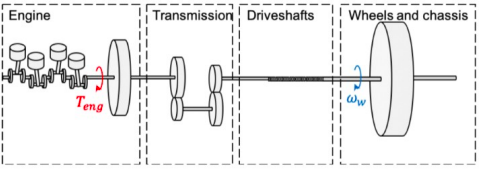

El sistema está descripto por las siguientes ecuaciones en espacio de estados:

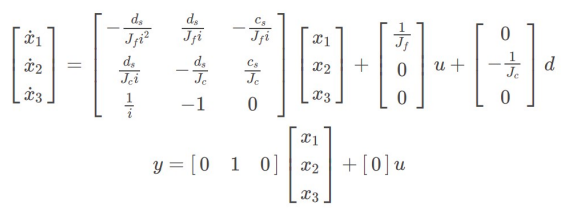

donde x1 es la velocidad del motor, x2 es la velocidad en las ruedas, x3 es el torque en árbol de transmisión (driveshafts), Δu es la señal de entrada, el torque del motor, y Δd es la perturbación, las variaciones en la superficie de la calzada.

Los parámetros del modelo son:

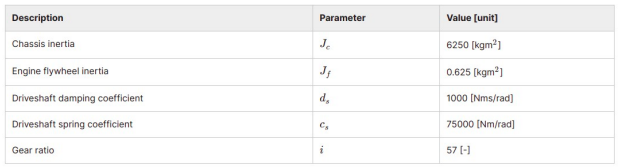

**1)** Se deben ubicar 3 polos del sistema. Dos polos se determinan al usar el polinomio carasterístico.

con ωn = 6 y ζ = 1/√2 . El tercer polo debe ser 2 veces más rápido que el resto de los polos, esto es, se debe ubicar en −2ζωn .

close all; clear all; clc;
% Solución en forma simbólica.
syms Jc Jf ds cs i s
disp('Matrices del sistema:')

Matrices del sistema:


A = [-ds/(Jf*i^2)  ds/(Jf*i) -cs/(Jf*i);
     ds/(Jc*i)    -ds/Jc      cs/Jc;
     1/i          -1          0]

$$A = \left(\begin{array}{ccc} -\frac{\mathrm{ds}}{\mathrm{Jf}\,i^{2}} & \frac{\mathrm{ds}}{\mathrm{Jf}\,i} & -\frac{\mathrm{cs}}{\mathrm{Jf}\,i}\\ \frac{\mathrm{ds}}{\mathrm{Jc}\,i} & -\frac{\mathrm{ds}}{\mathrm{Jc}} & \frac{\mathrm{cs}}{\mathrm{Jc}}\\ \frac{1}{i} & -1 & 0 \end{array}\right)$$

Bu = [1/Jf;0;0];
Bd = [0;-1/Jc;0];
B = Bu + Bd

$$B = \left(\begin{array}{c} \frac{1}{\mathrm{Jf}}\\ -\frac{1}{\mathrm{Jc}}\\ 0 \end{array}\right)$$

C = [0 1 0]

C =      0     1     0


D = [0]

D = 0

I = eye(3);
disp('Polinomio característico simbólico:')

Polinomio característico simbólico:


p_caracteristico = det(s*I-A)

$$p\_caracteristico = \frac{\mathrm{Jc}\,\mathrm{Jf}\,i^{2}\,s^{3}+\mathrm{Jf}\,\mathrm{ds}\,i^{2}\,s^{2}+\mathrm{Jf}\,\mathrm{cs}\,i^{2}\,s+\mathrm{Jc}\,\mathrm{ds}\,s^{2}+\mathrm{Jc}\,\mathrm{cs}\,s}{\mathrm{Jc}\,\mathrm{Jf}\,i^{2}}$$

A continuación se le agrega un valor númerico a cada parámetro.

% Parámetros númericos.
Jc = 6250;
Jf = 0.625;
ds = 1000;
cs = 75000;
i = 57;
% Matrices númericas.
A = [-ds/(Jf*i^2)  ds/(Jf*i) -cs/(Jf*i);
     ds/(Jc*i)    -ds/Jc      cs/Jc;
     1/i          -1          0];
Bu = [1/Jf;0;0];
Bd = [0;-1/Jc;0];
B = Bu + Bd;
C = [0 1 0];
D = [0];
disp('Polinomio característico:')

Polinomio característico:


p_caracteristico = det(s*I-A)

$$p\_caracteristico = s^{3}+\frac{52996\,s^{2}}{81225}+\frac{52996\,s}{1083}$$

C1_syms = coeffs(p_caracteristico,s); % Obtenemos los coeficientes simbólicos del polinomio característico.
C1_double = double(C1_syms); % Coeficientes formato double.
a3 = 0;
a2 = C1_double(1,1);
a1 = C1_double(1,2);

Procedemos ahora con la búsqueda del polinomio característico deseado:

wn = 6; % Frecuencia natural.
zeta = 1/sqrt(2); % Amortiguamiento relativo.
disp('Polinomio característico deseado:')

Polinomio característico deseado:


p_deseado = (s+2*zeta*wn)*(s^2 + 2*zeta*wn*s + wn^2) % Polinomio deseado.

$$p\_deseado = \left(s+6\,\sqrt{2}\right)\,\left(s^{2}+6\,\sqrt{2}\,s+36\right)$$

C2_syms = coeffs(p_deseado, s); % Coeficientes simbólicos del polinomio anterior.
C2_double = double(C2_syms); % Coeficientes en formato double.
p3 = C2_double(1,1);
p2 = C2_double(1,2);
p1 = C2_double(1,3);
disp('Polos del polinomio característico deseado:')

Polos del polinomio característico deseado:


polos = roots([1 p1 p2 p3]) % Polos del polinomio deseado.

polos =   -8.4853 + 0.0000i
  -4.2426 + 4.2426i
  -4.2426 - 4.2426i


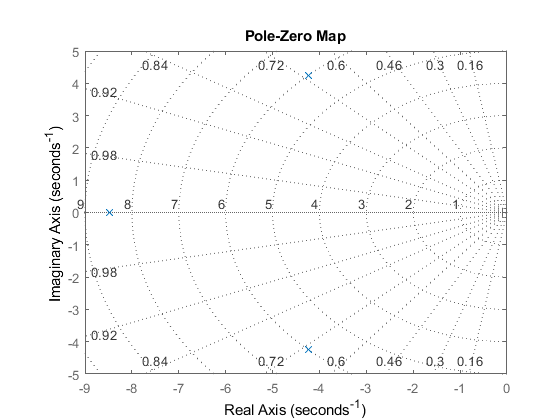

% Mostramos los polos en el plano complejo.
polos_deseados = tf(1,[C2_double(1,4) C2_double(1,3) C2_double(1,2) C2_double(1,1)]);
pzmap(polos_deseados);
grid on

**2)** Encuentre el valor de la matriz K de realimentación por el método de Ackermann.

Wr = [B A*B A^2*B]; % Matriz de alcanzabilidad.
Wr_tilde = inv([1 a1 a2;
                0 1  a1;
                0 0  1]);
K = [p1-a1 p2-a2 p3-a3]*Wr_tilde*inv(Wr)

K = 	1.0e+03 *

    0.0102    0.3398    1.9480


Kprima = 	1.0e+03 *

    0.0102    0.3398    1.9480


% Corroboración.
Kprima = acker(A,B,polos)

Kprima = 	1.0e+03 *

    0.0102    0.3398    1.9480


**3)** Encuentre el valor de kr.

Sabiendo que, para el control en espacio de estados por realimentación del vector de estado, se tiene:

Para eliminar el error de estado estacionario se pretende que:

Esto significa que en estado estacionario no tenemos variación del estado interno del sistema, de este modo:

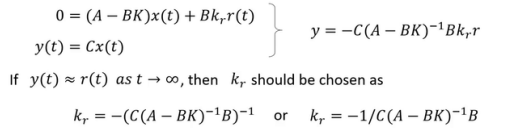

Con lo cual:

kr = -1/(C*inv(A-B*K)*B)

kr = 923.0585

**4)** Encuentre los autovalores del sistema a lazo cerrado.

autovalores = eig(A-B*K)

autovalores =   -8.4853 + 0.0000i
  -4.2426 + 4.2426i
  -4.2426 - 4.2426i


Se observa que los autovalores a lazo cerrado, es decir, los polos del sistema a lazo cerrado coinciden con los polos del polinomio característico planteado.

Se concluye entonces que los polos a lazo cerrado fueron colocados exitosamente.